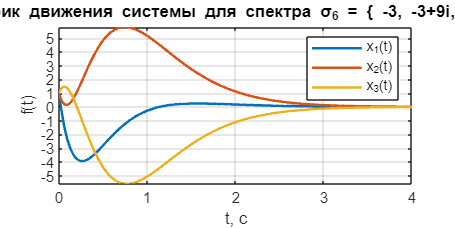

open_system('task_1_sim');
set_param('task_1_sim/x', 'VariableName', 'x')
set_param('task_1_sim/u', 'VariableName', 'u')
set_param('task_1_sim/u1', 'VariableName', 'u1')
set_param('task_1_sim/u2', 'VariableName', 'u2')

out = sim('task_1_sim');

figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5)
%hold on
%plot(out.y2,'--', 'LineWidth',1.5)
%plot(out.y3,'-.', 'LineWidth',1.5)

grid()
title('График движения системы для спектра σ_6 = \{ -3, -3+9i, -3-9i \}', 'Interpreter','tex')
legend('x_1(t)', 'x_2(t)', 'x_3(t)', 'Interpreter','tex')
ylabel('f(t)')
xlabel('t, с')
yticks([-6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6])

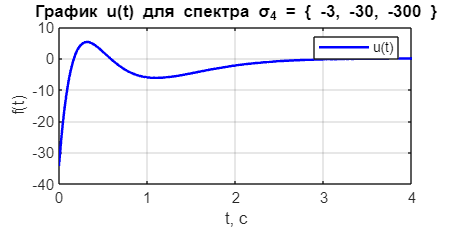

%hold off

plot(out.u,'b', 'LineWidth', 1.5)
%hold on
%plot(t, y,'b--', 'LineWidth', 1.5)

grid("on")
title('График u(t) для спектра σ_4 = \{ -3, -30, -300 \}', 'interpreter','tex')
legend('u(t)','Interpreter','tex')
ylabel('f(t)')
xlabel('t, с')

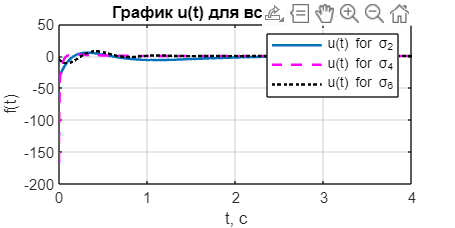

%ylim([-200 100])
%hold off

% для наглядности все графики u(t) на одной плоскости

plot(out.u, 'LineWidth', 1.5)
hold on
plot(out.u1,'m--', 'LineWidth', 1.5)
plot(out.u2,'k:', 'LineWidth', 1.5)
%plot(t, y,'b--', 'LineWidth', 1.5)

grid("on")
title('График u(t) для всех спектров', 'interpreter','tex')
legend('u(t) for σ_2', 'u(t) for σ_4', 'u(t) for σ_6','Interpreter','tex')
ylabel('f(t)')
xlabel('t, с')
hold off